# **Particle Image Velocimetry**

## Introduction

**Particle Image Velocimetry (PIV)** is a non-intrusive optical measurement technique used to obtain velocity fields in fluid flows. It enables the detailed visualization and quantitative analysis of flow dynamics by capturing the motion of tracer particles seeded into the fluid. PIV is widely applied in experimental fluid mechanics, including aerodynamics, microfluidics, and biomedical flows, due to its ability to provide instantaneous, two- or three-dimensional velocity data across a large area.

The fundamental principle of PIV involves seeding the fluid with small, neutrally buoyant particles that accurately follow the flow. These particles are illuminated (typically by a laser light sheet) and their motion is recorded using high-speed or double-frame cameras at short, known time intervals. By comparing the displacement of particles between successive images, the local velocity of the fluid can be inferred.

The standard PIV process includes the following steps:

- **Seeding and Illumination**: The fluid is seeded with tracer particles that are small enough to follow the flow but large enough to scatter sufficient light. A laser sheet illuminates a thin cross-section of the flow, enhancing particle visibility.

- **Image Acquisition**: A high-resolution camera captures sequential images of the illuminated particles at precisely controlled time intervals.

- **Velocity Field Calculation**: Using image pairs, the displacement of groups of particles is computed through cross-correlation algorithms applied to interrogation windows—small sub-regions of the image. These displacements, divided by the time interval, yield local velocity vectors.

- **Post-processing**: The raw velocity field is further refined through vector validation and filtering to remove noise and artifacts, ensuring a physically consistent dataset.

- **Data Analysis and Visualization**: The final velocity field can be used to derive additional flow quantities such as vorticity, shear rate, or turbulence characteristics, and is visualized through vector plots, contour maps, or other graphical methods.

The porpuse of this live script is ment to be a description of what a PIV Simple Pass algorithm looks like and what are the steps to follow.

## PIV Algoritm description

The steps for Performing PIV Analysis:

- **Pre-processing**: apply image enhancement techniques to improve particle visibility and contrast. Perform calibration to establish the spatial scale, linking pixel dimensions to physical distances.

- **Mask Creation**: generate masks to exclude non-relevant areas such as solid boundaries, obstacles, or regions without particles that could interfere with the analysis.

- **PIV Algorithm Execution**: use cross-correlation, typically via Fast Fourier Transform (FFT), to determine the average displacement of particles within interrogation windows between successive images. Convert these displacements into a velocity vector field.

- **Post-processing**: detect and remove spurious vectors using validation criteria and apply smoothing or filtering to ensure physical consistency in the velocity field.

- **Result Visualization**: plot velocity vectors, vorticity fields, and other derived quantities as needed for analysis and interpretation.

For this test-case we assume to work with two cameras taking images of a rotor inside a wind tunnel. The cameras are taking pictures of one next to portion of space that can then put next to each other to reconstruct the entire image.

Since the porpuse of this live-script is just to show the work-flow behind a PIV algorithm with a Simple-Pass approach, we will deal only with one couple of images. Mind that this process must then be iterated for several images to then average the results and reduce errors.

# `PIV Algorithm`

clear
close all
clc

First, we set the velocity of the flow field and define the size of the subdomain window using the variable `subdomain`. We also specify the overlap, which determines how many pixels the subdomain shifts during each step of the cross-correlation analysis.

**NOTE****:** An overlap value of 1 means the subdomain moves by 1 pixel at each iteration, providing maximum resolution. However, for faster computation, you can use a higher value (i.e., less overlap).

% Initial settings
velocity = 9; % m/s
subdomain = 32; % 32x32 pxl
overlap = 50; % Overlapping 50%

## 1. Pre-processing

First of all we perform a pre-process of the images to improve visualization.

% Load calibration images
calibImgPath = fullfile("data","Calib", "Cam2", "Cam2_0001.b16");
imgCalib = readB16(calibImgPath);

% Convert and adjust visualization
imgCalib_normalized = mat2gray(imgCalib);

mat2gray requires Image Processing Toolbox.

imgCalib_cont = imadjust(imgCalib_normalized);
% Appply filter
imgCalib_filt = medfilt2(imgCalib_cont);

Then we compute the spatial calibration, to determine the scale factor between pixel distances in the image and real-world distances. This **magnification factor** is calculated using a reference grid of evenly spaced points, allowing accurate measurement specific to the experiment.

% Find circles to apply the calibration
[centers, radii] = imfindcircles(imgCalib_filt, [20 500], 'ObjectPolarity', 'dark', 'Sensitivity', 0.9);

figure()
hold on
imshow(imgCalib_filt)
viscircles(centers(5,:), radii(5), 'EdgeColor', 'b');
viscircles(centers(12,:), radii(12), 'EdgeColor', 'r');
axis on
xlabel('X (pixel)')
ylabel('Y (pixel)')
title('Calibration image')
hold off

% Spatial calibration
dist_real = 17.57; % in mm
dist_pix = sqrt((centers(5,1) - centers(12,1))^2 + (centers(5,2) - centers(12,2))^2);
magn = dist_pix/dist_real; % pixel/mm
fprintf('Magnification Factor: %f pxl/mm \n', magn)

Finally the time calibration is performed following the literature, with the "1/4 rule" meaning the average particle displacement between exposures should be about one-quarter of the sampling window size. In our case, the sampling window used in post-processing is 32 × 32 pixels.

% Temporal calibration (1/4 rule)
avg_displacement_pxl = 1/4 * subdomain;
avg_mean_displacement = avg_displacement_pxl/magn;
dt = avg_mean_displacement/velocity*1e-3 % s

## 2. Create a mask

Create a mask to hide the obstacles to avoid problems when computing the particles displacements

%makeMask("ask"); % Uncomment this to create your own mask
mask = importdata('mask');

## 3. Start the cycle

If we have two cameras capturing *n* images each at two different time steps, the process follows these steps:

- Import the *i*-th images from both cameras at two consecutive time steps.

- Pre-process the images to enhance visualization.

- Fuse the two images to reconstruct the scene and apply the mask.

- Apply the PIV algorithm.

- Average the results over all *n* image pairs.

**NOTE****:** This process can be very computationally demanding. Using the Parallel Computing Toolbox can significantly reduce processing time—potentially by half.

In this example, we demonstrate the procedure using only one pair of images.

%Load images
cam1_t = fullfile("data","9ms","Cam1","Cam1_0001A.b16");
cam1_dt = fullfile("data","9ms","Cam1","Cam1_0001B.b16");
cam2_t = fullfile("data","9ms","Cam2","Cam2_0001A.b16");
cam2_dt = fullfile("data","9ms","Cam2","Cam2_0001B.b16");

% Pre-processing
cam1_t_filt = filter_image(cam1_t, [0.001 0.05]);

mat2gray requires Image Processing Toolbox.

Error in filter_image (line 6)
    imag_normalized = mat2gray(imag); 

cam1_dt_filt = filter_image(cam1_dt, [0.023 0.074]);
cam2_t_filt = filter_image(cam2_t, [0.01 0.45]);
cam2_dt_filt = filter_image(cam2_dt, [0.27 0.69]);

% Reconstruct the two images and apply mask
img_t_filt = [cam2_t_filt, cam1_t_filt];
img_t_filt(mask) = NaN;
img_dt_filt = [cam2_dt_filt, cam1_dt_filt];
img_dt_filt(mask) = NaN;

### **PIV Algorithm:**

- Divide each image into small, **overlapping interrogation windows**.

- Use **cross-correlation** to compare corresponding windows between two successive images.

- Identify the **peak of the correlation function** to determine the average particle displacement within each window.

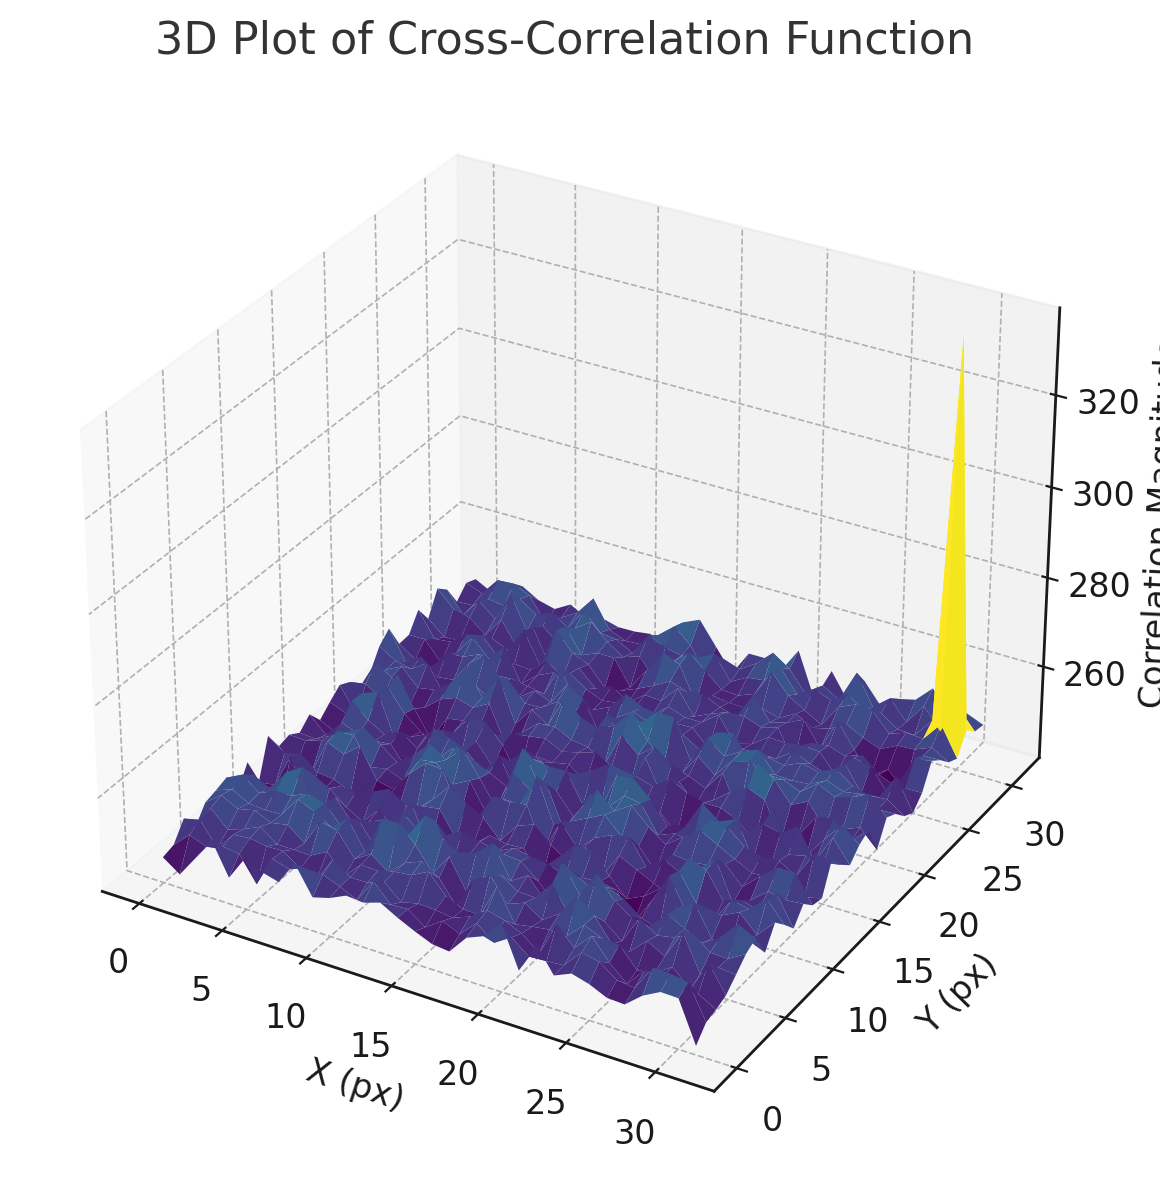

- Apply **sub-pixel interpolation** around the correlation peak to increase accuracy and reduce displacement estimation errors.

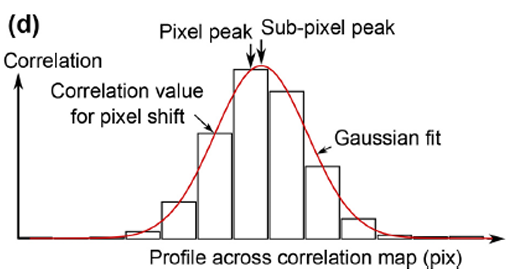

% Create a computational grid of the domain
[x_grid, y_grid] = meshgrid(1:overlap:(2*size(imgCalib_filt, 2) - subdomain), ...
                            1:overlap:(size(imgCalib_filt, 1) - subdomain)); 
% Initialize velocity Matrix
U = zeros(size(x_grid));
V = zeros(size(y_grid));

% Initialize variables for sub-pixel intepolation
[X, Y] = meshgrid(-1:1, -1:1);
A = [X(:).^2, Y(:).^2, X(:).*Y(:), X(:), Y(:), ones(9, 1)];

% Extract windows for the entire grid from both images
for i = 1:(size(x_grid, 1))
    for j = 1:(size(x_grid,2))
        
        x_start = x_grid(i, j);
        y_start = y_grid(i, j);
        x_end = x_start + subdomain - 1;
        y_end = y_start + subdomain - 1;

        % Extract interrogation window at t
        window1 = img_t_filt(y_start:y_end, x_start:x_end);
        
        % Extract iterrogation window at t+dt
        window2 = img_dt_filt(y_start:y_end, x_start:x_end);

        % Apply Fast Fourier Trasnsform
        F1 = fft2(window1);
        F2 = fft2(window2);
    
        % Compute the correlation
        C = real(ifft2(F1 .* conj(F2)));
        
        % Shift and find the correlation peak
        [maxval, max_idx] = max(C(:));
        [dy_sub, dx_sub] = ind2sub(size(C), max_idx);
        
        if isnan(maxval)
            dx_sub = 0;
            dy_sub = 0;
        end
         
        if dx_sub > subdomain/2
            dx_sub = dx_sub - subdomain;
        end
         
        if dy_sub > subdomain/2
            dy_sub = dy_sub - subdomain;
        end
    
        % Sub-pixel interpolation (parabolic)
        if dx_sub > 1 && dx_sub < size(C, 2) && dy_sub > 1 && dy_sub < size(C, 1)
    
            neighborhood = C(dy_sub-1:dy_sub+1, dx_sub-1:dx_sub+1);
            b = neighborhood(:);
            coeff = A\b;
            dx_sub1 = -coeff(4) / (2 * coeff(1));
            dy_sub1 = -coeff(5) / (2 * coeff(2));
            % Adjust w.r.t. global system
            dx_sub = dx_sub1 + dx_sub - 2;
            dy_sub = dy_sub1 + dy_sub - 2;  
    
        end
        
        % Reconstruct velocity
        U(i,j) = (dx_sub .* (1/magn).*1e-3) ./ dt; % m/s
        V(i,j) = (dy_sub .* (1/magn).*1e-3) ./ dt; % m/s
    end
end

### Vector validation

We can check that the results are "dirty" due to errors in the images and correlation process:

figure()
imshow(img_t_filt)
hold on
h = quiver(x_grid, y_grid, U, V, 'Color', 'r','AutoScaleFactor',3);
set(h, 'Color', 'r');
set(gca, 'YDir', 'reverse');
xlabel('X (pixel)')
ylabel('Y (pixel)')
title('"Dirty" results')
hold off

So filters to remove spurious vectors must be applied.

- Apply **validation filters** to remove spurious vectors (e.g. global threshold, local median check).

- Remove outlayers (vector that are out of the frame)

- Remove noise (high velocity vectors, high velocity gradients)

% Apply filters
U = imgaussfilt(U);
V = imgaussfilt(V);
U_filt = medfilt2(U, [3 3]);  
V_filt = medfilt2(V, [3 3]);  


% Remove spurus velocity vectors
[allU(:,:,1), allV(:,:,1), dU_dx, dV_dy] = vectorValidation(U_filt, V_filt);

Now the vector field is clean:

figure()
imshow(img_t_filt)
hold on
h = quiver(x_grid, y_grid, allU, allV, 'Color', 'r','AutoScaleFactor',3);
set(h, 'Color', 'r');
set(gca, 'YDir', 'reverse');
xlabel('X (pixel)')
ylabel('Y (pixel)')
title('Results')
hold off

## 6. Post - processing

Finally once we get the results of the velocity vector field we can visualize it with colormap, streamlines, ...

% Magnitude velocity
magnVelocity = sqrt(allU.^2 + allV.^2);

% Vorticity
[du_dy, ~] = gradient(allU);
[~, dv_dx] = gradient(allV);
vorticity1 = dv_dx - du_dy;
vorticity2 = dU_dx - dV_dy;

% Velocity field colormap + streamlines
figure()
contourf(x_grid, y_grid, magnVelocity, 140, 'LineColor', 'none')
hold on
colormap(jet)
colorbar
clim([0 12])
h = streamslice(x_grid, y_grid, allU, allV); 
set(h, 'Color', 'k');
set(gca, 'YDir', 'reverse');
title('Mean velocity magnitude')
xlabel('X (pixel)')
ylabel('Y (pixel)')
hold off

% Vorticity field colormap
figure()
contourf(x_grid, y_grid, vorticity1, 'LineColor', 'none')
colorbar
colormap(parula)
clim([-6 6])
title('Mean vorticity field')
set(gca, 'YDir', 'reverse')
xlabel('X (pixel)')
ylabel('Y (pixel)')

**NOTE:**

To have good results we must repete this process for several couple of images and then average the results among all of them in that way you get results like these: